## The Lotka-Volterra model

The Lotka-Volterra is defined as


$$\frac{dx_1}{dt}=a x_1 - b x_1x_2 \\ \frac{dx_2}{dt}=c x_1 x_2 - d x_2 $$


where $a,b,c,d$ are real constants. The LotkaVolterra script inside the Models folder will return a function handle for the ODE. For some arbitrary parameters, the results are the following.

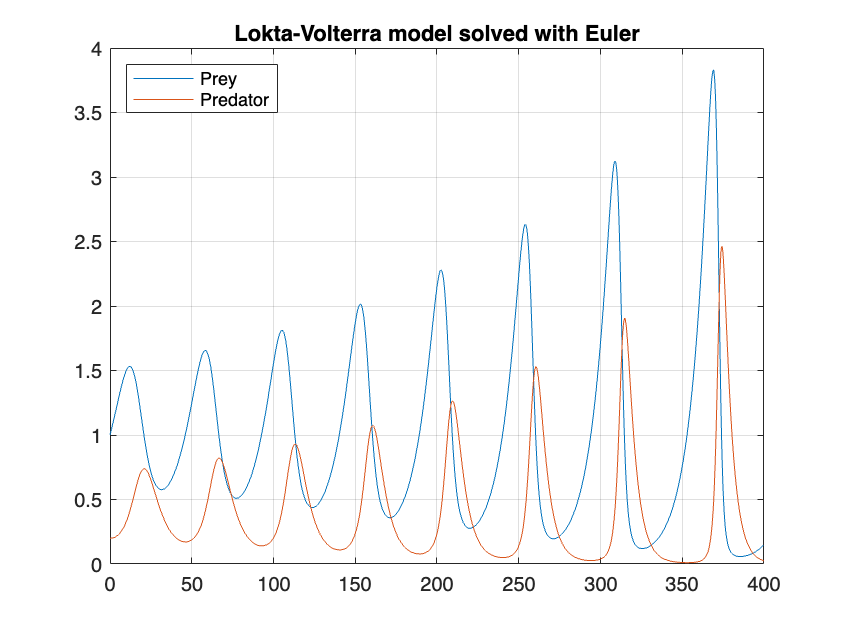

a = 0.1; b = 0.25; c = 0.2; d = 0.2;
prey = 1; predator = 0.2; n = 1000; t_end = 400;

f = LotkaVolterra(a,b,c,d);

[x,t] = Euler(f, 0, t_end, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Lokta-Volterra model solved with Euler")

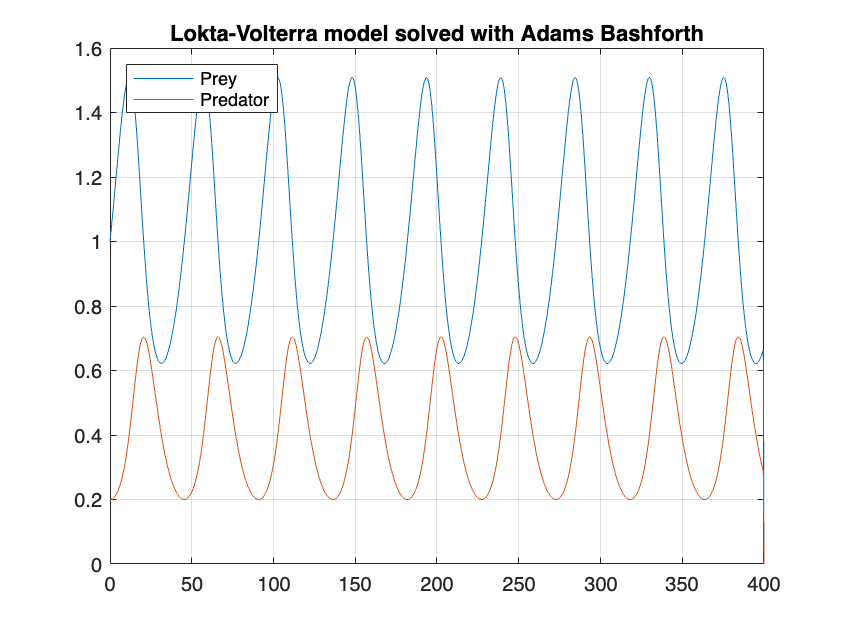


[x,t] = AdamsBashforth(f, 0, t_end, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Lokta-Volterra model solved with Adams Bashforth")

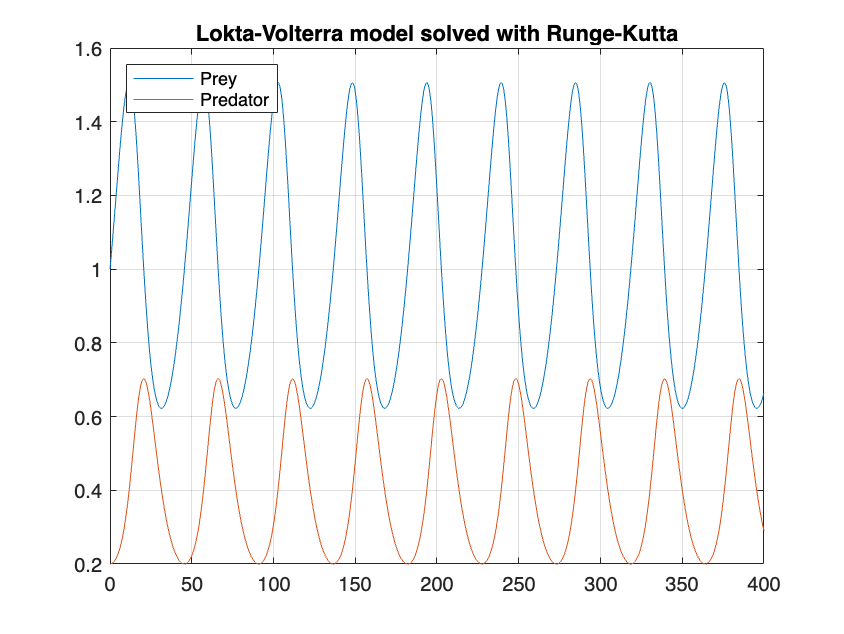


[x,t] = RungeKutta(f, 0, t_end, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Lokta-Volterra model solved with Runge-Kutta")

Note how for Euler's method, the oscillations grow increasingly larger, due to it being a method not suitable for problems with exponential solutions, due to the fast growth or decay not being easily aproximatable using linear functions. This would ultimately lead to the numerical solution exploding, despite the model being stable. However, all these methods protray the fundamental behavior of this simple system, showing the out of phase oscillations of the system.

## Ecological modelling

Values can also be fitted to real world datasets, or derived to produce biologically plausible results. For example, assuming rabbits and foxes, with no other species or phenomenons, the following values (in monthly rates) can be taken.

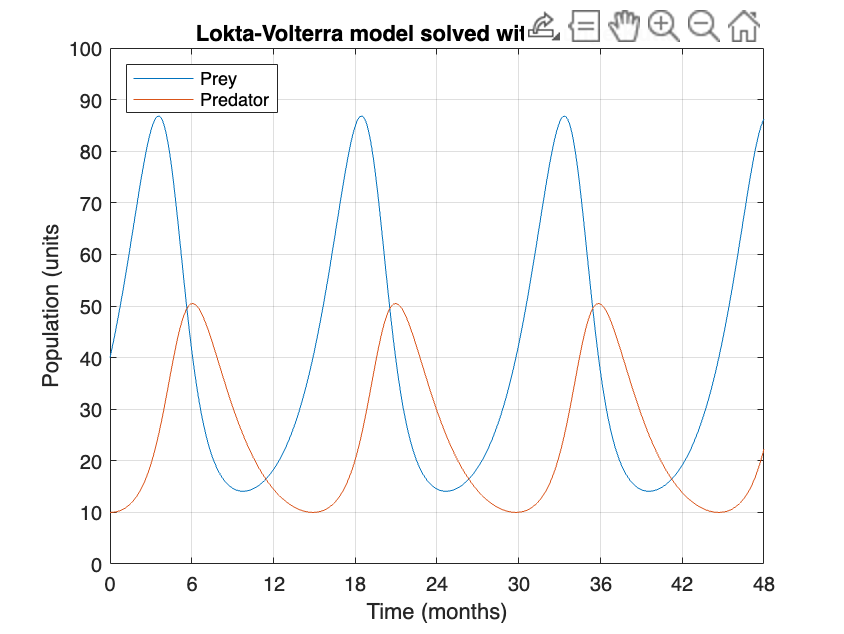

a = 0.5;  % Prey grows by 50% monthly in absence of predators
b = 0.02; % Prey encounters per month per predator
c = 0.01; % Predator efficiency (in converting prey into offspring)
d = 0.4;  % Predator population declines by 40% monthly in absence of prey

prey = 40; predator = 10; n = 1000; t_end = 48;

f = LotkaVolterra(a,b,c,d);
[x,t] = RungeKutta(f, 0, t_end, [prey; predator], n);
plot(x,t)
grid
legend("Prey","Predator",location="northwest")
title("Lokta-Volterra model solved with Runge-Kutta")
xlim([0 48])
ylim([0 100])
xticks(0:6:48)
ylabel("Population (units")
xlabel("Time (months)")

Note how the choice of suitable parameters allow for stable and biologically plausible results.